# visualizing b_sec at one time - 3d

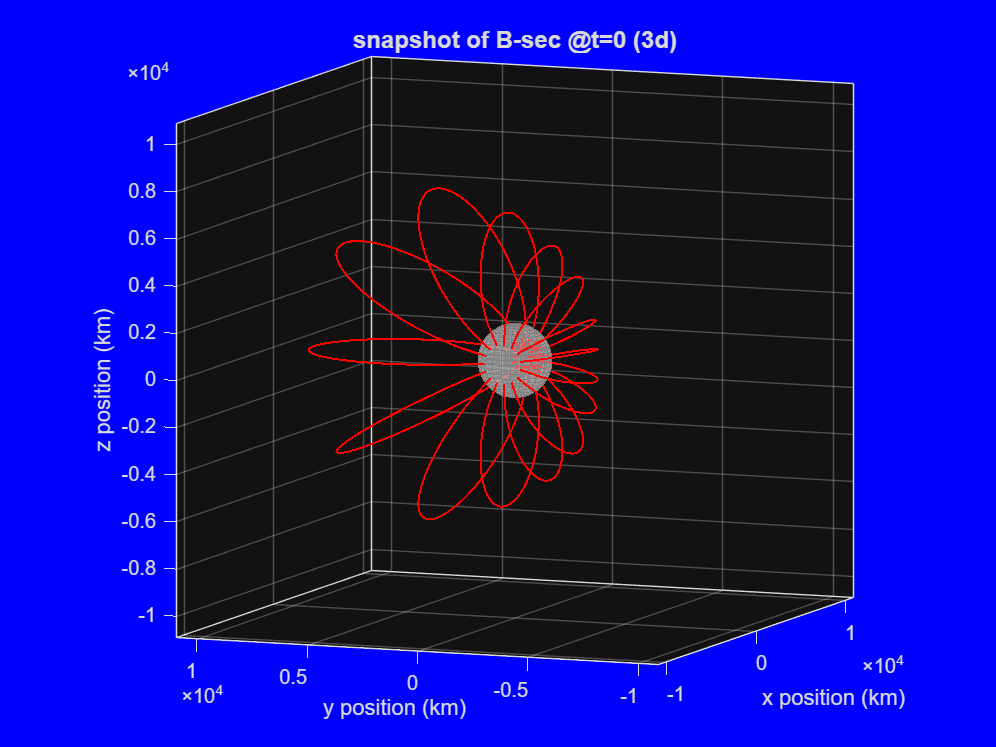

clear
% define constants

r_m = 1560; % Europa radius (km)
B_prim = 250; % approximate background field amplitude nT
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians (around 8 deg)
omega = 2*pi / (11.23 * 3600); % synodic freq. (rad/sec), 11.23 hr period

t = 0;

% inducing field direction
e0x = [1;0;0];
e0y = [0;1;0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create spatial grid 
grid_limit = 7 * r_m; % view up to 7 planetary radii out 
[X,Y,Z] = meshgrid(linspace(-grid_limit, grid_limit, 30), ...
    linspace(-grid_limit,grid_limit, 30), ...
    linspace(-grid_limit, grid_limit, 30));


% compute secondary field components (bx,by,bz) at every point 
% initialize arrays to hold magnetic field vector components

Bx_spatial = zeros(size(X));
By_spatial = zeros(size(X));
Bz_spatial = zeros(size(X));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% loop through each grid point to calculate the spatial part of eqn (3)
for i = 1:numel(X)

    % define position vector r from center of moon
    r_vec = [X(i); Y(i); Z(i)];
    r = norm(r_vec);

    % mask field inside the moon to avoid division by 0
    if r < r_m
        continue;
    end


    % X EQUATION
    % calculate dot prod (r . e0x)
    r_dot_e0x = dot(r_vec, e0x);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_bracketx = 3 * r_dot_e0x * r_vec - (r^2) * e0x;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coefx = - (A * B_prim * r_m^3) * (cos (omega * t - phi)) / (2 *r^5);


    % Y EQUATION
    % calculate dot prod (r . e0y)
    r_dot_e0y = dot(r_vec, e0y);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_brackety = 3 * r_dot_e0y * r_vec - (r^2) * e0y;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coefy = - (A * B_prim * r_m^3) * (sin (omega * t - phi)) / (2 *r^5);



    % store vector components
    B_vector = (coefx * spatial_bracketx) + (coefy * spatial_brackety);
    Bx_spatial(i) = B_vector(1);
    By_spatial(i) = B_vector(2);
    Bz_spatial(i) = B_vector(3);    

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Bx = Bx_spatial;
By = By_spatial;
Bz = Bz_spatial;




figure('Color', 'b');
set(gcf, 'Position', [100, 100, 800, 600]);
hold on;

% setting seeds
theta = linspace(0, 2*pi, 16); 
seed_radius = 1.05 * r_m; 


y1 = seed_radius * 0.5 * cos(theta);
z1 = seed_radius * 0.5 * sin(theta);
x1 = ones(size(theta)) * seed_radius * 0.85;


y2 = seed_radius * 0.5 * cos(theta);
z2 = seed_radius * 0.5 * sin(theta);
x2 = ones(size(theta)) * -seed_radius * 0.85;


seed_X = [x1, x2];
seed_Y = [y1, y2];
seed_Z = [z1, z2];

% draw Europa as 3d sphere
[sx, sy, sz] = sphere(24);
mesh(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor',[0.5 0.5 0.5]);
alpha(0.4);


% plot mag field vectors
h1 = streamline(X,Y,Z,Bx,By,Bz,seed_X(:), seed_Y(:), seed_Z(:));



set(h1, 'Color', 'r', 'LineWidth', 1);

% grid formatting
axis equal; 
xlim([-grid_limit, grid_limit]);
ylim([-grid_limit, grid_limit]);
zlim([-grid_limit, grid_limit]);
xlabel('x position (km)', 'FontSize', 11);
ylabel('y position (km)', 'FontSize', 11);
zlabel('z position (km)', 'FontSize', 11);
title('snapshot of B-sec @t=0 (3d)', 'FontSize', 12);
grid on;
box on;
    
view(3);
rotate3d on;

view([-68 8]);